close all; clear; clc;

load('TrainingSamplesDCT_8_new.mat')
BG_num = size(TrainsampleDCT_BG,1);
FG_num = size(TrainsampleDCT_FG,1);

C = 8; % number of components
dim_list = [1,2,4,8,16,24,32,40,48,56,64];

%% image import
zz_order = dlmread('Zig-Zag Pattern.txt');
img = imread('cheetah.bmp');
img = im2double(img);
[row,col] = size(img);
ground_truth = imread('cheetah_mask.bmp')/255;
%imshow(img);
N = 8;     

imgDCT_matrix = zeros((row-N+1) * (col-N+1), 64);
count = 0;
for r = 1:row-N+1
    for c = 1:col-N+1
        count = count + 1;
        sub_img = img(r:r+N-1, c:c+N-1); % 8*8 block image
        sub_img_DCT = dct2(sub_img); 
        sub_img_vec = DCT_zz(sub_img_DCT, zz_order); 
        imgDCT_matrix(count,:) = sub_img_vec;
                % The ouput DCT coefficients vector following zz order
    end
end

## (a) 5 foreground and 5 background mixture models with 8 components:

%% Problem (a)

err_25 = []; % (1,11),5,5 = dim, FG, BG
for bg = 1: 5
    %% BG EM
    pi_BG = randi(1, C);
    pi_BG = pi_BG / sum(pi_BG);
    mu_BG = TrainsampleDCT_BG(randi([1 BG_num],1,C), :);
    var_BG = zeros(64,64,8);
    for i = 1:C
        var_BG(:,:,i) = (rand(1,64)) .* eye(64);
    end

    EM_iteration = 1000;
    P_Z_X = zeros(BG_num, C);
    likelihood = zeros(1000,1);
    for i = 1: EM_iteration
        % E-step
        for j = 1:C
            P_Z_X(:,j) = mvnpdf(TrainsampleDCT_BG, mu_BG(j,:), var_BG(:,:,j)) ...
                .* pi_BG(j);
        end
        hij = P_Z_X ./ sum(P_Z_X,2);
        likelihood(i) = sum(log(sum(P_Z_X,2)));%
        % M-step
        pi_BG = sum(hij) / BG_num;
        mu_BG = hij' * TrainsampleDCT_BG ./ sum(hij)';
        for j = 1:C
            var_BG(:,:,j) = diag(diag((TrainsampleDCT_BG - mu_BG(j,:))'.* hij(:,j)' * ...
                (TrainsampleDCT_BG - mu_BG(j,:)) ./ sum(hij(:,j),1))+0.0000001);
        end

        if i > 1
            if abs(likelihood(i) - likelihood(i-1)) < 0.001
                break; 
            end
        end
    end

    %% FG_EM
    err_same_bg = [];
    for fg = 1:5
        pi_FG = randi(1, C);
        pi_FG = pi_FG / sum(pi_FG);
        mu_FG = TrainsampleDCT_FG(randi([1 FG_num],1,C), :);
        var_FG = zeros(64,64,8);
        for i = 1:C
            var_FG(:,:,i) = (rand(1,64)) .* eye(64);
        end

        EM_iteration = 1000;
        P_Z_X = zeros(FG_num, C);
        likelihood = zeros(1000,1);
        for i = 1: EM_iteration
            % E-step
            for j = 1:C
                P_Z_X(:,j) = mvnpdf(TrainsampleDCT_FG, mu_FG(j,:), var_FG(:,:,j)) ...
                    .* pi_FG(j);
            end
            hij = P_Z_X ./ sum(P_Z_X,2);
            likelihood(i) = sum(log(sum(P_Z_X,2)));%
            % M-step
            pi_FG = sum(hij) / FG_num;
            mu_FG = hij' * TrainsampleDCT_FG ./ sum(hij)';
            for j = 1:C
                var_FG(:,:,j) = diag(diag((TrainsampleDCT_FG - mu_FG(j,:))'.* hij(:,j)' * ...
                    (TrainsampleDCT_FG - mu_FG(j,:)) ./ sum(hij(:,j),1))+0.0000001);
            end

            if i > 1
                if abs(likelihood(i) - likelihood(i-1)) < 0.001
                    break; 
                end
            end
        end

        %% Classification
        err_tmp = zeros(1,length(dim_list));
        mask_matrix = zeros(row-N+1, col-N+1, length(dim_list));
        for dim_i = 1:length(dim_list)
            dim = dim_list(dim_i);
            mask = zeros((row-N+1) * (col-N+1),1);
            for n = 1:size(imgDCT_matrix,1)
                p_BG = 0;
                p_FG = 0;
                % Px|y is mixture gaussian 
                for c = 1:C
                    p_BG = p_BG + mvnpdf(imgDCT_matrix(n,1:dim), mu_BG(c, 1:dim), ...
                        var_BG(1:dim,1:dim,c)) * pi_BG(c);
                    p_FG = p_FG + mvnpdf(imgDCT_matrix(n,1:dim), mu_FG(c, 1:dim), ...
                        var_FG(1:dim,1:dim,c)) * pi_FG(c);
                end
                % BDR
                if p_BG < p_FG
                    mask(n) = 1;
                end
            end
            % Reshape
            mask_tmp = zeros(row-N+1, col-N+1);
            row_count = 0;
            for r = 1:row-N+1
                row_count = row_count + 1;
                mask_tmp(r,:) = mask((row_count-1) * (col-N+1) + 1 : ...
                (row_count) * (col-N+1));
            end
            mask_matrix(:,:,dim_i) = mask_tmp;

            % Error
            err_tmp(dim_i) = sum(sum(ground_truth(1:row-N+1,1:col-N+1) ~= mask_tmp)) / row / col; 
        end
        err_same_bg = cat(3,err_same_bg,err_tmp);
    end
    err_25 = cat(4,err_25,err_same_bg);
end

for bg = 1:5
    figure
    hold on
    grid on
    box on
    title("PoE in BG"+string(bg))
    for fg = 1:5
        ylabel("Probability of Error")
        xlabel("Number of Dimensions")
        plot(err_25(:,:,fg,bg), "o-");
    end
    legend("FG1","FG2","FG3","FG4","FG5")
    savefig("PoE in BG"+string(bg))
end

The plot of POE with respect to different number of dimensions is shown above. As we can see, the combination of different foreground and background mixture models will generate different results(probability of error), which is caused by initialization during the EM training. Also we can observe that with the increase of the number of dimensions, the difference between the results increases.

However, we can observe that the general trend of all 25 models are really similar. With more dimensions, the probablility of error generally decreases. If we select the best 8 features, the result will be better than using all 64 features. As we can see from the result of this homework, for all 25 models the POE doesn't reach its minimum when we use all 64 dimensions. The number of dimensions that have the best probability of error varies within all 25 models, but generally it is betwenn 24 to 48.

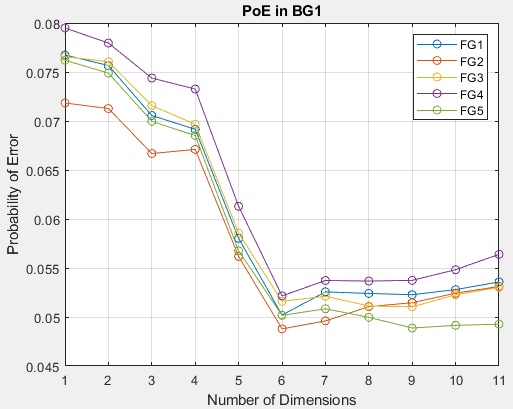

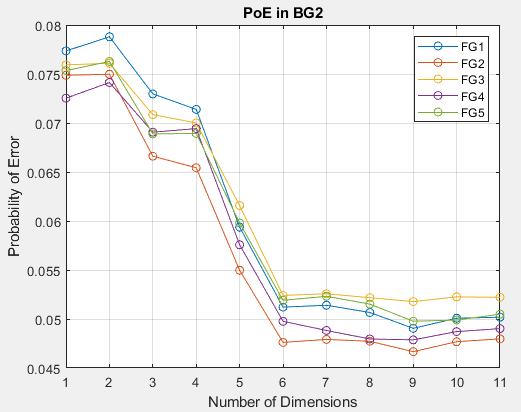

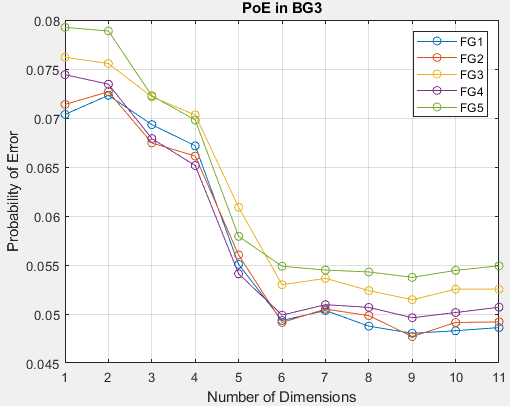

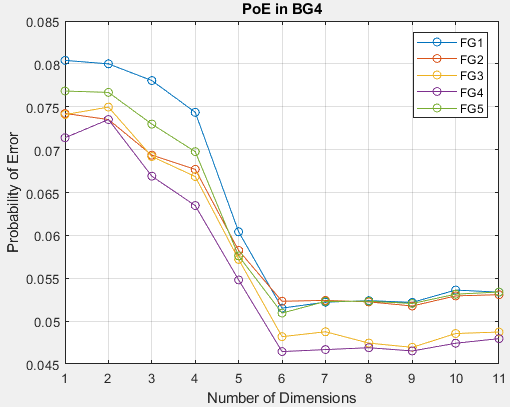

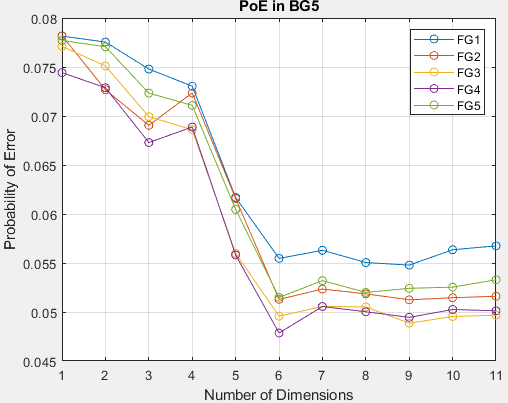

## b) Mixture models with different numbers of components:

%% BG EM
C_list = [1,2,4,8,16,32];
err_C = [];
for c_i = 1:length(C_list)
    C = C_list(c_i);
    pi_BG = randi(1, C);
    pi_BG = pi_BG / sum(pi_BG);
    mu_BG = TrainsampleDCT_BG(randi([1 BG_num],1,C), :);
    var_BG = zeros(64,64,8);
    for i = 1:C
        var_BG(:,:,i) = (rand(1,64)) .* eye(64);
    end

    EM_iteration = 1000;
    P_Z_X = zeros(BG_num, C);
    likelihood = zeros(1000,1);
    for i = 1: EM_iteration
        % E-step
        for j = 1:C
            P_Z_X(:,j) = mvnpdf(TrainsampleDCT_BG, mu_BG(j,:), var_BG(:,:,j)) ...
                .* pi_BG(j);
        end
        hij = P_Z_X ./ sum(P_Z_X,2);
        likelihood(i) = sum(log(sum(P_Z_X,2)));%
        % M-step
        pi_BG = sum(hij) / BG_num;
        mu_BG = hij' * TrainsampleDCT_BG ./ sum(hij)';
        for j = 1:C
            var_BG(:,:,j) = diag(diag((TrainsampleDCT_BG - mu_BG(j,:))'.* hij(:,j)' * ...
                (TrainsampleDCT_BG - mu_BG(j,:)) ./ sum(hij(:,j),1))+0.0000001);
        end

        if i > 1
            if abs(likelihood(i) - likelihood(i-1)) < 0.001
                break; 
            end
        end
    end

    %% FG_EM
    pi_FG = randi(1, C);
    pi_FG = pi_FG / sum(pi_FG);
    mu_FG = TrainsampleDCT_FG(randi([1 FG_num],1,C), :);
    var_FG = zeros(64,64,8);
    for i = 1:C
        var_FG(:,:,i) = (rand(1,64)) .* eye(64);
    end

    EM_iteration = 1000;
    P_Z_X = zeros(FG_num, C);
    likelihood = zeros(1000,1);
    for i = 1: EM_iteration
        % E-step
        for j = 1:C
            P_Z_X(:,j) = mvnpdf(TrainsampleDCT_FG, mu_FG(j,:), var_FG(:,:,j)) ...
                .* pi_FG(j);
        end
        hij = P_Z_X ./ sum(P_Z_X,2);
        likelihood(i) = sum(log(sum(P_Z_X,2)));%
        % M-step
        pi_FG = sum(hij) / FG_num;
        mu_FG = hij' * TrainsampleDCT_FG ./ sum(hij)';
        for j = 1:C
            var_FG(:,:,j) = diag(diag((TrainsampleDCT_FG - mu_FG(j,:))'.* hij(:,j)' * ...
                (TrainsampleDCT_FG - mu_FG(j,:)) ./ sum(hij(:,j),1))+0.0000001);
        end

        if i > 1
            if abs(likelihood(i) - likelihood(i-1)) < 0.001
                break; 
            end
        end
    end

    %% Classification
    err_tmp = zeros(1,length(dim_list));
    mask_matrix = zeros(row-N+1, col-N+1, length(dim_list));
    for dim_i = 1:length(dim_list)
        dim = dim_list(dim_i);
        mask = zeros((row-N+1) * (col-N+1),1);
        for n = 1:size(imgDCT_matrix,1)
            p_BG = 0;
            p_FG = 0;
            % Px|y is mixture gaussian 
            for c = 1:C
                p_BG = p_BG + mvnpdf(imgDCT_matrix(n,1:dim), mu_BG(c, 1:dim), ...
                    var_BG(1:dim,1:dim,c)) * pi_BG(c);
                p_FG = p_FG + mvnpdf(imgDCT_matrix(n,1:dim), mu_FG(c, 1:dim), ...
                    var_FG(1:dim,1:dim,c)) * pi_FG(c);
            end
            % BDR
            if p_BG < p_FG
                mask(n) = 1;
            end
        end
        % Reshape
        mask_tmp = zeros(row-N+1, col-N+1);
        row_count = 0;
        for r = 1:row-N+1
            row_count = row_count + 1;
            mask_tmp(r,:) = mask((row_count-1) * (col-N+1) + 1 : ...
            (row_count) * (col-N+1));
        end
        mask_matrix(:,:,dim_i) = mask_tmp;

        % Error
        err_tmp(dim_i) = sum(sum(ground_truth(1:row-N+1,1:col-N+1) ~= mask_tmp)) / row / col; 
    end
    err_C = cat(3,err_C,err_tmp);
end

figure
hold on
grid on
box on
title("PoE with Different Number of Mixture Components")
ylabel("Probability of Error")
xlabel("Number of Dimensions")
for c_i = 1:length(C_list)
    plot(err_C(:,:,c_i), "o-");    
end
legend("C = 1","C = 2","C = 4","C = 8","C = 16", "C = 32", "Location", "southwest")
savefig("PoE with Different Number of Mixture Components")

As we can see from the result, the POE of the mixture model with only 1 component is strictly larger than the results of the rest of the models. Thus we can conclude that, using only 1 component cannot best fit the true distribution of $P_{X|Y}(x|i)$, in other words $P_{X|Y}(x|i)$ is not just a simple multivariate Gaussian distribution. With more components the trend of different curves are generally the same. In this experiment, using 32 components can give us the best probability of error. However, the optimal number of components cannot be revealed from this single experiment.

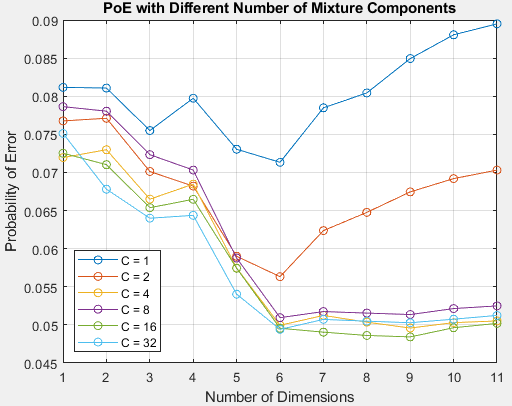

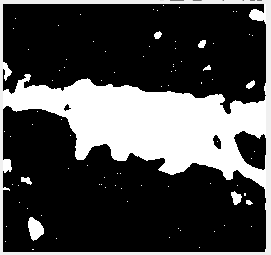 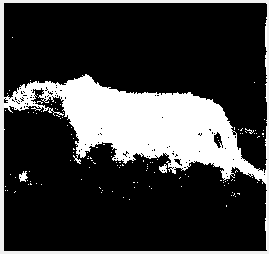

                      C = 1                                               C = 32